## MATH2070 Project  2016

Name - Rahul Vemulapally

SID - 440317463

Date - 21/10/2016

Project completed in MATLAB Live Script File format (.mlx) and exported to PDF format.

All the explanations, plots/images, code, and output are inline and follow a linear order.

# **Given information:**

clear; format compact; format shortG;
info = readtable('tablegiven.csv'); disp(info);

    Security    Code     Return    Risk 
    ________    _____    ______    _____
    'P1'        'BHP'    0.055     0.018
    'P2'        'NAB'     0.07     0.016
    'P3'        'CSR'     0.11     0.022
    'P4'        'AGL'    0.115     0.036
    'P5'        'NCP'    0.125     0.048


name = char(info.Code);

# Fund Returns ($\mu_i$)

rBHP = 0.055;
rNAB = 0.070;
rCSR = 0.110;
rAGL = 0.115;
rNCP = 0.125;
vec_r = [rBHP; rNAB; rCSR; rAGL; rNCP];

# Fund Risk $(\sigma_i)$

sdBHP = 0.018;
sdNAB = 0.016;
sdCSR = 0.022;
sdAGL = 0.036;
sdNCP = 0.048;
vec_sd = [sdBHP; sdNAB; sdCSR; sdAGL; sdNCP];

# Fund Variance $(\sigma^2)$

vec_var = vec_sd.^2;
Tvar = table(name, vec_var, 'VariableNames', {'Fund', 'Variance'});
disp(Tvar);

    Fund    Variance
    ____    ________
    BHP     0.000324
    NAB     0.000256
    CSR     0.000484
    AGL     0.001296
    NCP     0.002304


# Correlation  Matrix$(\rho_{i,j})$

mat_cor = zeros(5,5);
mat_cor(1,3) = -0.25;             % BHP and CSR have negative correlation
mat_cor(3,1) = -0.25;             % BHP and CSR have negative correlation
mat_cor(2,5) = 0.55;              % NAB and NCP have Positive correlation
mat_cor(5,2) = 0.55;              % NAB and NCP have Positive correlation
mat_cor(1:6:end) =1;
disp(mat_cor);

            1            0        -0.25            0            0
            0            1            0            0         0.55
        -0.25            0            1            0            0
            0            0            0            1            0
            0         0.55            0            0            1


# Covariance Matrix - S

S = diag(vec_sd)*mat_cor*diag(vec_sd);  disp(S);

     0.000324            0     -9.9e-05            0            0
            0     0.000256            0            0    0.0004224
     -9.9e-05            0     0.000484            0            0
            0            0            0     0.001296            0
            0    0.0004224            0            0     0.002304


# Question 1

Investors who short sell in this market are the ones with the risk aversion parameter $(t) $that satisfies the below inequality:

## Short Sell   $\Longrightarrow$   $x_i(t) = \alpha_i + \beta_i t \leq 0$       i.e.,  the values of $t$for which the critical line is negative.

Equivalently, investors that DO NOT short sell are the ones with the risk aversion parameter $(t) $that satisfies the below inequality:

## **DO NOT Short Sell   **$\Longrightarrow$  $x_i(t) = \alpha_i + \beta_i t \geq 0$     i.e.,  the values of $t$for which the critical line is positive.

e = ones(5,1);

## Inverse of Covariance Matrix

Sinv = inv(S)                    % Inverse of Covariance Matrix

Sinv =        3292.2            0        673.4            0            0
            0       5600.4            0            0      -1026.7
        673.4            0       2203.9            0            0
            0            0            0        771.6            0
            0      -1026.7            0            0       622.26

a = e'*Sinv*e;
b = e'*Sinv*vec_r;
c = vec_r'*Sinv*vec_r;
d = a*c-b^2;
alpha = (1/a)*Sinv*e;
beta = Sinv*(vec_r-((b/a)*e));
con_name = {'a';'b';'c';'d'};
con_vals = [a;b;c;d];
Tcons = table(con_name, con_vals, 'VariableNames',{'Constants','ConstantValues'});
disp(Tcons);

    Constants    ConstantValues
    _________    ______________
    'a'           11784        
    'b'          892.93        
    'c'          74.175        
    'd'           76715        


# Alpha $(\alpha)$

disp(alpha);

      0.33653
      0.38813
      0.24417
     0.065481
    -0.034325


sum(alpha)

ans =      1

# Beta $(\beta)$

disp(beta);

      -45.359
      -82.896
       61.429
       30.264
       36.561


round(sum(beta))

ans =      0

## Finding the values of t, where the critical line is postive, i.e., these $t$ values DO NOT require short-selling.

Therefore, we need to find the values of $t$ that satisfy the following five inequalities:

for BHP:   $0.33653  +  (-45.359)* (t)  \geq  0$

for NAB:   $0.38813  +  (-82.896)* (t)  \geq  0$

for CSR:   $0.24417 + (61.429)* (t) \geq 0$

for AGL:   $0.065481 + (30.264)* (t) \geq 0$

for NCP: $-0.034325 + (36.561)* (t) \geq 0$

## If $  \alpha + \beta (t)  \geq 0$, then $t \geq \frac{-\alpha}{\beta}$, solving for t, we get:

lb =(-alpha)./beta; %find lower bound for t parameter when x(t) = 0
ub = repelem(inf,5)';          

As Beta for BHP and NAB are negative, we flip the bounds.

ub(1,1) = lb(1,1);
lb(1,1) = -inf;
ub(2,1) = lb(2,1);
lb(2,1) = -inf;
T2 = table(name,lb,ub,'VariableNames',{'Fund','LowerBound','UpperBound'});

**Upper and lower bounds of **$t$** for each Fund with NO short selling.**

disp(T2);      

    Fund    LowerBound    UpperBound
    ____    __________    __________
    BHP           -Inf    0.0074194 
    NAB           -Inf    0.0046822 
    CSR     -0.0039749          Inf 
    AGL     -0.0021637          Inf 
    NCP     0.00093883          Inf 


lbt = max(lb);   ubt= min(ub);

**Range of **$t$**tha****t satisfy all five inequalities stated above are, i.e.,**$ t$** values for which there will be NO short selling:**

fprintf('Lower Bound = %.4e \nUpper Bound =  %.4e\n', lbt,ubt);

Lower Bound = 9.3883e-04 
Upper Bound =  4.6822e-03


**Comments:**

**        Investors with the risk aversion parameter **$(t)$** within the above range **$[ 0.0009388,   0.004682 ]$** will NOT short sell any of the funds but  investors with **$t$**outside this range will short sell.**

                    For $t < 0.0009388$, the investor will not short sell any funds except NCP as we only consider $t \geq 0$. 

                    For $t > 0.004682$, the investor can short sell NAB and BHP but not CSR, AGL or NCP.

**       The only funds that no one will short sell are CSR and AGL due to the requirement that  **$t $** needs to be  **$\geq 0$**, i.e., the critical line is positive **$\forall t \in [0 , \infty)$** for CSR and AGL.**   

# Minimum risk Portfolio (i.e., when t = 0):

mu_mvp = b/a          % mu for t = 0 on the MVF, or expected return from MVP

mu_mvp =      0.075778

sig_mvp = 1/sqrt(a)        % corresponding sigma for t = 0, risk for the MVP

sig_mvp =     0.0092122

# Question 2   - Hypatia's optimal portfolio - *P**

## Q2 (a)  

**Optimal allocation for Hypatia  is given by     **$x_i(0.007) = \alpha_i + \beta_i (0.007)$

cap = 200000;                       % Capital
t = 0.007;                          % Risk Aversion Parameter of Hypatia
x_hy = alpha + beta*(t);            % Optimal allocation
c_hy = cap*x_hy;                    % Capital allocation

**Expected return on Hypatia's optimal portfolio **$(\mu_{Hypatia})$**:**

mu_hy = x_hy'*vec_r                 % Expected return on Hypatia's portfolio

mu_hy =       0.12135

**Hypatia's optimal portfolio variance **$(\sigma_{Hypatia}^2)$**:**

var_hy = x_hy'*S*x_hy               % Hypatia's portfolio variance

var_hy =    0.00040387

**Hypatia's optimal portfolio risk **$(\sigma_{Hypatia})$:

sig_hy = sqrt(var_hy)                % Hypatia's portfolio risk (SD)

sig_hy =      0.020096

format long G;
Txhy = table(name, x_hy, c_hy, ...
        'VariableNames',{'Fund', 'Optimal_Allocation','Capital_Allocation'});

 **Optimal allocation and dollar investment in the five funds for Hypatia :**

Note - Capital allocation is in $'s.

disp(Txhy);

    Fund    Optimal_Allocation    Capital_Allocation
    ____    __________________    __________________
    BHP     0.0190216325228673     3804.32650457345 
    NAB     -0.192134592789243    -38426.9185578486 
    CSR      0.674178645895665     134835.729179133 
    AGL      0.277329724532205     55465.9449064411 
    NCP      0.221604589838504     44320.9179677009 


sum(Txhy.Capital_Allocation)

ans =         2e+05

format shortG;

## Q2 (b)  - $\mu\sigma$- plane plots


t_EF = (0:0.001:0.02);                % 0 < t < 0.02
t_IEF = (-0.02:0.001:0);                % -0.02 < t < 0
mu_EF = (b+d*t_EF)/a;
mu_IEF = (b+d*t_IEF)/a;
sig_EF = sqrt((1+d*t_EF.^2)/a);
sig_IEF = sqrt((1+d*t_IEF.^2)/a);

## Q2 (c)  -  1000 random feasible portfolios satisfying $|x_i| \leq 2.5 $:

First, initializing the random number generator with seed = 0 to make the results repeatable.

rng(0,'twister');

**Generating N rand****om numbers in the interval (a,b) with the formula r = a + (b-a).*rand(N,1).**

Note - *rand* function draws the values from a uniform distribution in the open interval (a, b), it does not include the end points!

count = 0;
j = 0;
x = zeros(5,1000);
while j<1000
    count = count+1; 
    xtemp = -2.5 + (5).*rand(5,1);   ...
        % generate 5 random numbers in the interval (-2.5, 2.5)
    xtemp = xtemp/sum(xtemp);        ...
        % Making each column sum to 1:
        if (sqrt(xtemp'*S*xtemp) <= 0.05);   ...
                % calculate sigma and  check if sigma <= 0.05
            j=j+1;                       ...
                % if success increment j and accept x values
            x(:,j) = xtemp;
        end
    end
% iterations required to generate 1000 feasible portfolios with sigam <= 0.05
count    

count =         1685

size(x)

ans =            5        1000

sum(sum(abs(x) > 2.5))                     % checking |x_i| < 2.5

ans =      0

**Calculating **$\mu_i  \quad and\quad \sigma_i$** for the 1000 portfolios:**

for j=1:1000
    mu_i(j) = x(:,j)'*vec_r;
    sig_i(j) = sqrt(x(:,j)'*S*x(:,j));
end
sum(sig_i > 0.05)       % checking to make sure sigma <= 0.05

ans =      0

## Hypatia's Indifference Curve:

Using the  Utility function: $U(\mu, \sigma) = F(t\mu - \frac{1}{2}\sigma^2)$  to find the indifference curve.

Negative of $U(\mu, \sigma)$   is   $Z(\mu, \sigma) = -t\mu +  \frac{1}{2}\sigma^2$   and Minimizing $Z(\mu, \sigma) $    maximizes $U(\mu, \sigma)$.

Expressed using the asset allocations, we get         $Z(\vec{x}) = -t(\vec{r}'\vec{x}) + \frac{1}{2}(\vec{x}'S\vec{x})$

Using **Hypatia's optimal portfolio variance **$(\sigma_{Hypatia}^2)$ and **expected return **$(\mu_{Hypatia})$ to calculate the minimum of the above objective function $Z(\mu, \sigma) $.

% minimum of the objective function for Hypatia's optimal portfolio return and variance
z = -t*mu_hy + (1/2)*var_hy   

z =   -0.00064752

sd_ind = (0:0.001:0.05);
mu_ind = (-z + (1/2)*(sd_ind.^2))/t;        % points for indifference curves
mu_ind1 = (-(z-0.0001) + (1/2)*(sd_ind.^2))/t;
mu_ind2 = (-(z+0.0001) + (1/2)*(sd_ind.^2))/t;

## Plots:

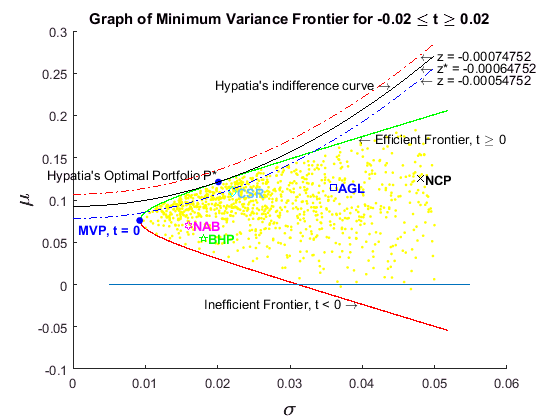

figure(2);
hold on
plot(sig_i,mu_i,'.y');     % 1000 feasible portfolios mu and sigma
plot(sdBHP, rBHP, 'pg');
text(sdBHP+0.0001,rBHP,'\color{green} BHP','FontWeight','bold');
plot(sdNAB, rNAB, 'hm');
text(sdNAB+0.0001,rNAB,'\color{magenta} NAB','FontWeight','bold');
plot(sdCSR, rCSR, 'dc');
text(sdCSR+0.0001,rCSR,'\color{lightBlue} CSR','FontWeight','bold');
plot(sdAGL, rAGL, 'sb');
text(sdAGL+0.0001,rAGL,'\color{blue} AGL','FontWeight','bold');
plot(sdNCP, rNCP, 'xk');
text(sdNCP+0.0001,rNCP,'\color{black} NCP','FontWeight','bold');
plot(sig_EF,mu_EF,'g', 'LineWidth', 1);        % Efficient Frontier
txtEF = '\leftarrow Efficient Frontier, t \geq 0';
text(sig_EF(end-5),mu_EF(end-5),txtEF);
plot(sig_IEF,mu_IEF,'r', 'LineWidth', 1);       % Inefficient Frontier
txtIEF = 'Inefficient Frontier, t < 0 \rightarrow';
text(sig_IEF(end-15),mu_IEF(end-15), txtIEF,...
    'HorizontalAlignment','right');
refline(0,0);
xlabel('\sigma','FontSize', 16, 'FontWeight', 'bold');
ylabel('\mu','FontSize', 16, 'FontWeight', 'bold');
title('Graph of Minimum Variance Frontier for -0.02 \leq t \geq 0.02');
plot(sig_hy, mu_hy, '.b', 'MarkerSize', 15);  % Hypatia's optimal portfolio mu and sigma
txtOP = 'Hypatia''s Optimal Portfolio P*';
text(sig_hy, mu_hy+0.01,txtOP,'HorizontalAlignment','right');
plot(sig_mvp, mu_mvp, '.b', 'MarkerSize', 15);   % Minimum Variance Portfolio, t = 0
txtMVP = 'MVP, t = 0';
text(sig_mvp, mu_mvp-0.01, txtMVP, 'color' , 'blue','FontWeight','bold', ...
    'HorizontalAlignment','right')
plot(sd_ind,mu_ind, '-k');
txtIND = 'Hypatia''s indifference curve \rightarrow';
text(sd_ind(end-5)-0.001,mu_ind(end-5), txtIND, 'color', 'black',...
    'HorizontalAlignment','right');
txtINz = ['\leftarrow z* = ',num2str(z)];
text(sd_ind(end-2),mu_ind(end-2), txtINz);
plot(sd_ind,mu_ind1, '-.r');
txtINz1 = ['\leftarrow z = ',num2str(z-0.0001)];
text(sd_ind(end-2),mu_ind1(end-2), txtINz1);
plot(sd_ind,mu_ind2, '-.b');
txtINz2 = ['\leftarrow z = ',num2str(z+0.0001)];
text(sd_ind(end-2),mu_ind2(end-2), txtINz2);
hold off

## Legend: 

- P*             -        Hypatia's Optimal Portfolio

- MVP          -       Minimum Variance Portfolio, where risk aversion parameter $(t) = 0$. 

- Yellow dots     -  1000 random feasible portfolios

## Comments:

- Set of all feasible portfolios for the given five funds fall within the Mean variance Frontier (the hyperbola formed by the  efficient and inefficient frontiers).

- All the efficient portfolios fall on the top half of the Mean Variance Frontier (shown in green) and as such, Hypatia's optimal portfolio   $(P^*) $  is on the Efficient Frontier. 

- Hypatia's indifference curve (z = -0.00064752) is convex and the Efficient Frontier is concave, the unique point at which both these curves are tangential is given by the optimum portfolio $P^* = (\mu^* , \sigma^*)$ = (0.12135 , 0.020096)   and this portfolio offers the maximum expected utility of all the feasible portfolios.

# Question 3  - Adding Riskless Cash Fund - CAPM

r0 = 0.04;                     % risk-free rate
r_new = vec_r - r0             % modified rate of return

r_new =                      0.015
                      0.03
                      0.07
                     0.075
                     0.085

## New Optimal Allocation in risky assets under CAPM given by $\vec{x} = t(S^{-1}\bar{r})$

x_hy_new = t*(Sinv*r_new)      % New Optimal Allocation under CAPM 

x_hy_new =          0.675645342312009
         0.565169504181601
          1.15059687786961
         0.405092592592593
         0.154632118677818

sum(x_hy_new)    % Sum of risky assest is  > 1, meaning the investor needs to borrow

ans =           2.95113643563363

   c_bar is defined as:  $\bar{C} =\bar{r}'S^{-1}\bar{r}$

c_bar = r_new'*Sinv*r_new      

c_bar =           21.5938887490085

## Expected return under CAPM, i.e., when riskless fund is added to the portfolio, is given by  $\hat{\mu} = r_0 + \bar{c}t$

mu_new = r0 + t*c_bar          % New Expected return

mu_new =           0.19115722124306

## Variance is given by  $\hat{\sigma}^2 = \bar{c}t^2 = (\hat{\mu} - r_0)t$

var_new = t^2*c_bar            % New Variance

var_new =        0.00105810054870142

check_var = (mu_new-r0)*t        % Gives the same value

check_var =        0.00105810054870142

sig_new = sqrt(var_new)        % new Portfolio risk

sig_new =         0.0325284575210909

## Allocation in Riskless cash fund (borrowing to invest in risky funds):

x0 = 1- sum(x_hy_new)             % Allocation in Riskless cash fund

x0 =          -1.95113643563363

names = cellstr(name);  names{end+1} = 'Riskless';
x_tot = x_hy_new;     x_tot(end+1) = x0;    sum(x_tot)

ans =      1

format longG;
cap_tot = x_tot.*cap;

## Total amount of capital invested in risky assets (including the borrowed funds):

inv_risk = sum(x_hy_new.*cap);  % Total amount of capital invested in risky assets

## Capital borrowed at 4 % :

borrow = x0*cap;            % Borrowed capital              
Tcapm = table(names, x_tot, cap_tot, ...
        'VariableNames', {'Funds', 'Allocation', 'Cap_Allocation'});

## New Allocation including the Riskless fund.

disp(Tcapm);

      Funds          Allocation         Cap_Allocation  
    __________    _________________    _________________
    'BHP'         0.675645342312009     135129.068462402
    'NAB'         0.565169504181601      113033.90083632
    'CSR'          1.15059687786961     230119.375573921
    'AGL'         0.405092592592593     81018.5185185185
    'NCP'         0.154632118677818     30926.4237355635
    'Riskless'    -1.95113643563363    -390227.287126725


inv_risk = sum(Tcapm.Cap_Allocation(1:5));
fprintf('Total funds invested in risky assets = $%.2f \nBorrowed Funds = $%.2f\n',...
    inv_risk, abs(borrow));

Total funds invested in risky assets = $590227.29 
Borrowed Funds = $390227.29


inv_risk - cap             % check borrowed funds

ans =    3.9023e+05

format shortG;

**Total optimal ****allocation towards the risky assets is 2.9511 ($590, 227), which means Hypatia has to borrow 1.9511 ($390, 227) at 4% to invest in risky assets.**

# Tangency Portfolio

It is the portfolio given by the point in $\mu\sigma$-plane that is at the intersection of the Capital Market Line and the risky-asset Efficient Frontier. This portfolio contains no riskless asset and sums to 1.

## Expected return from the tangency portfolio is given by $\hat{\mu_T} = \frac{c - br_0}{b - ar_0}$  ,

mu_t = (c - b*r0)/(b - a*r0)        % Expected return from the tangency portfolio

mu_t =       0.09122

## Portfolio variance on the Efficient Frontier corresponding to a portfolio return of $r_o = 4\%$ is given by $\sigma_o^2 = \frac{\bar{c}}{d}$

% Portfolio Variance on EF for the risky assets only 
%   (which corresponds to a portfolio return of 4%)
var_0 = c_bar/d              

var_0 =    0.00028148

##  Tangency portfolio risk is given by $\hat{\sigma_T} = \frac{\hat{\mu} - r_0}{\sigma_0\sqrt{t}}$

sig_t = sqrt(var_0*d)/(b - a*r0)    % Risk corresponding to tangency portfolio return

sig_t =      0.011022

##   t - value corresponding to the Tangency Portfolio is given by  $t_T = \frac{1}{b - ar_0}$

  t_t  = 1/(b - a*r0)                % t value corresponding to tangency portfolio

t_t =      0.002372

  t_r0 = 1/sqrt(c_bar)                % t value corresponding to r0 or when risk = 0

t_r0 =        0.2152

## Allocation for the Tangency Portfolio (does not include the risk-free cash fund, just the risky funds) is given by $\vec{x} = t(S^{-1}\bar{r})$:

x_t = t_t*(Sinv*r_new)            % Tangency portfolio allocation

x_t =       0.22894
      0.19151
      0.38988
      0.13727
     0.052397

sum(x_t)

ans =             1

# Q4 Capital Market Line

## The Capital Market Line (CML) is given by $\hat{\sigma} = \frac{\hat{\mu} - r_0}{\sigma_0\sqrt{t}}$** , **where $r_0$ is the riskfree rate,  $\sigma_o^2$  is the portfolio variance on the Efficient frontier corresponding to a portfolio return of $r_o$.

This CML line is the degenerate form of the efficient frontier when one of the assets is riskless. 

## Note: from the definition of CML:    $\hat{\sigma} = \frac{\hat{\mu} - r_0}{\sigma_0\sqrt{d}} =\sqrt{\bar{c}}t$              as   $\bar{c} =  \bar{r}'S^{-1}\bar{r}  = d\sigma_0^2
$  ,  $\bar{r} = r - r_0$       and  $\hat{\mu} = r_0 + \bar{c}t$

There is a linear relation between sigma and t.

## Few more indifference curves:

sig_ind2 = (0:0.001:0.05);
z_mvp = -t*(mu_mvp) + (1/2)*(sig_mvp^2)    % Indifference curve tangential to MVP

z_mvp =   -0.00048801

z_capm = -t*(mu_new) + (1/2)*(sig_new^2);
z_vals = (-0.001:0.00035:0.0002);
z_vals(end+1) = z;
z_vals(end+1) = z_capm;
txtz = cell(length(z_vals),1);
for i = 1:length(z_vals)
    mu_ind5{i} = (-z_vals(i) + (1/2)*(sig_ind2.^2))/t;
    txtz{i,:} = ['z = ',num2str(z_vals(i))];
end
txtz;
for i = 1:length(z_vals)
       txtIC = txtz{i,1};
       y = mu_ind5{1,i}(end-1);
    
end

# Q4 Plot:

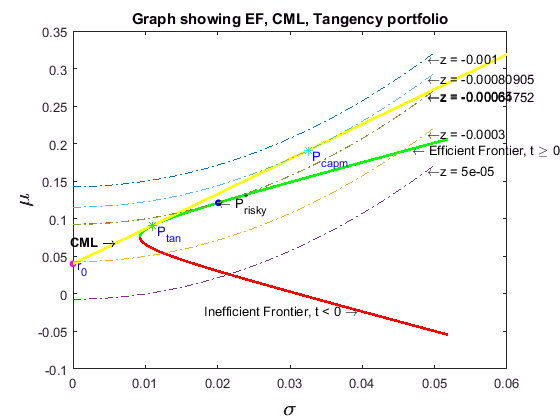

sig_cml = (0:0.001:0.06); 
mu_cml = sig_cml*sqrt(c_bar)+r0;           % calculating CML points
figure(3);
plot(0,0.04, '.m', 'MarkerSize', 15);
text(0, 0.036, '\color{blue} r_{0}');
hold on
title('Graph showing EF, CML, Tangency portfolio');
plot(sig_EF,mu_EF,'g', 'LineWidth', 2);        % Efficient Frontier
txtEF = '\leftarrow Efficient Frontier, t \geq 0';
text(sig_EF(end-2),mu_EF(end-2),txtEF);
plot(sig_IEF,mu_IEF,'r', 'LineWidth', 2);       % Inefficient Frontier
txtIEF = 'Inefficient Frontier, t < 0 \rightarrow';
text(sig_IEF(end-15),mu_IEF(end-15), txtIEF,...
    'HorizontalAlignment','right');
plot(sig_cml,mu_cml, 'y', 'LineWidth', 2);            % CML line
txtCML = 'CML \rightarrow';
text(sig_cml(7), mu_cml(7)+0.002, txtCML,'FontWeight','bold',...
    'HorizontalAlignment','right');
plot(sig_new, mu_new, '*c');  
    % Hypatia's new portfolio allocation including the risk-free fund
text(sig_new, mu_new-0.01, '\color{blue} P_{capm}');
plot(sig_t, mu_t, '*g');              % Tangency Portfolio
text(sig_t, mu_t-0.01, '\color{blue} P_{tan}');
plot(sig_hy, mu_hy, '.b', 'MarkerSize', 15); 
                        % Hypatia's optimal portfolio without risk-free fund
txtOP = '\leftarrow P_{risky}^*';
text(sig_hy, mu_hy,txtOP);
xlabel('\sigma','FontSize', 16, 'FontWeight', 'bold');
ylabel('\mu','FontSize', 16, 'FontWeight', 'bold');
for i = 1:length(z_vals)
    plot(sig_ind2,mu_ind5{i}, '-.');
    txtIC = ['\leftarrow',txtz{i,1}];
   text(0.049, mu_ind5{1,i}(end-1), txtIC)
end
hold off

Legend:

- $P_{risky}^* -$ Hypatia's Optimal Portfolio without the riskless fund

- $P_{tan}  -$   Tangency Portfolio

- $P_{capm}  -$  Hypatia's Optimal Portfolio with the riskless fund     

- CML -    Capital Market line 

- $r_0   -  $         Risk-free return of 4%

Comments:

- By introducing the risk-free fund the Efficient Frontier degenerates into the Capital Market Line, which dominates all the efficient portfolios available on the efficient frontier except for the Tangency Portfolio.

- If Hypatia did not have the option of risk-free fund, then the optimal portfolio is given by the point $P_{risky}^*  $ , this portfolio offers the maximum Utility (for the specific Utility function $U(\mu, \sigma) = F(t\mu - \frac{1}{2}\sigma^2)$)  as the objective function  $Z(\mu, \sigma) = -t\mu +  \frac{1}{2}\sigma^2$ is minimized for $\mu \enspace and  \beta $ given by  the point $P_{risky}^*  $.   Also this point is tangential to the indifference curve z = - 0.0006475, and is where the objective function achieves the minimum for the available set of feasible portfolios. 

-  The objective function moves northwest as the function decreases.

- z =  - 0.001 is smaller than - 0.0006475 but it is outside the feasible set. 

- z = - 0.0003 is greater  than -0.0006475 and does offer choices of feasible portfolios but they are not optimal

- z = - 0.0006475, offers the optimal portfolio when there is no option of investing in the risk-free fund.

- Z = - 0.00080905, offers a better optimal portfolio when the option of investing in the risk-free fund  is available, this  indifference curve  offers higher expected utility compared to the indifference curve z = - 0.0006475 (without the choice of risk-free asset).

- In summary, if Hypatia  had the option of investing in the risk-free fund, then the optimum portfolio is given by $P_{capm}$  on the Capital Market line tangential to the  indifference curve z = - 0.00080905, this portfolio offers the maximum expected utility  of all the feasible portfolios. 

## Estimating the total value of each fund  (to the nearest $0.1 million) for the combined net worth of $100 million:

This is calculated using the Tangency Portfolio as weights.

net = 100000000;
f_vals = x_t*net;
tvals = num2str(f_vals, '%-.1f\n');
Tval = table(name, x_t, tvals, 'VariableNames',{'Fund','Allocation','Dollar_Value'});
disp(Tval);

    Fund    Allocation    Dollar_Value
    ____    __________    ____________
    BHP      0.22894      22894412.3  
    NAB      0.19151      19150910.7  
    CSR      0.38988      38988264.5  
    AGL      0.13727      13726664.3  
    NCP     0.052397      5239748.2
  


sum(f_vals)

ans =    100000000

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%